# Adaptive control for positioning systems

## Adaptive control strategy: Self tuning controller

sqareWaveGen = @(t, T)((t - T*floor(t/T)) < T/2);

Kf0 = 3;
Tf0 = 5;
Te = 0.1;
T = 300*Te;
t = 0:Te:5*T;
u = sqareWaveGen(t, T);

Hf = tf(Kf0, [Tf0 1 0]);
wn = 1;
zeta = 1;
Hfd = c2d(Hf, Te, 'zoh');
[num, den] = tfdata(Hfd, 'v');

system = DiscreteModelZoh(num(2:end), den(2:end));
[num, den] = getDiscreteCompensator(den(2), num(2), Te, wn, zeta);


controller = DiscreteModel(num, den(2:end));
Hcd = tf(num, den, Te);

error = zeros(length(u), 1);
output = zeros(length(u), 1);
command = zeros(length(u), 1);
error(1) = u(1);
m = floor(length(u)/2);
aux = m;

## Initialization

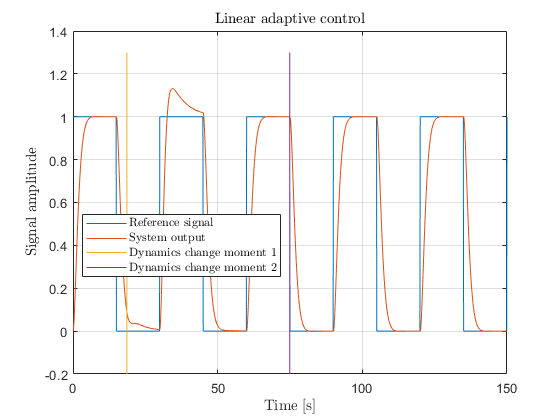

% system polynomial orders
na = 2;
nb = 1;
nd = 1;
windowSize = 180; % observation vector and measurements size
wIdx = 1;
window = zeros(na + nb + 1, 1); 
inputBuffer = zeros(nd, 1);
outputBuffer = zeros(1, 1);
wY = zeros(windowSize, 1); % measurements
phi = zeros(nb + na + 1, windowSize); % observation vector

% Optimizer utility functions
evalGradient = @(theta, phi, y)(-sum((y - theta'*phi).*phi, 2));
evalHessian = @(phi)(phi*phi');
evalCost = @(theta, phi, y)(sum((y - theta'*phi).^2));
alpha = 1; % optimizer step
beta = 1.1; % bactracking step increment
alphaUpperThreshold = 10000; % step upper boundary
alphaBottomTreshold = 0.00000001; % step bottom boundary

% paramters to optimize
[num, den] = tfdata(Hfd, 'v');
theta = [num(2:end)'; den(2:end)'];
theta = [theta theta];

% non-zero intial conditions avoidance
timeUnitsToWait = max(nb + nd, na);
timeUnitsWaited = 0;
isReady = false;
f = 1;
changeTime = zeros(2, 1);
for i = 1:length(u)-1
    [controller, command(i)] = forward(controller, error(i));
    [system, output(i), nextRes] = forward(system, command(i));
    error(i + 1) = u(i + 1) - nextRes;
    
    if i == floor(length(u)/8) || i == floor(length(u)/2) 
        Kf = normrnd(Kf0, 2);
        %Kf = Kf + 10;
        Tf = normrnd(Tf0, 1);
        Hf = tf(Kf, [Tf 1 0]);
        Hfd = c2d(Hf, Te, 'zoh');
        [num, den] = tfdata(Hfd, 'v');
        system.num = num(2:end);
        system.den = den(2:end);
        changeTime(f) = t(i);
        f = f + 1;
        m = m + aux;
    end
    
    if nd >= 1
        window(1) = inputBuffer(1);
    else
        window(1) = command(i);
    end
    for j = 2:nb+1
        if wIdx - 1 >= 1
            window(j) = phi(j - 1, wIdx - 1);
        end
    end
    if nd > 1 
        inputBuffer(1:end-1) = inputBuffer(2:end);
        inputBuffer(end) = command(i);
    else
        inputBuffer = command(i);
    end
    
    window(nb + 2) = -outputBuffer;
    for k = nb+3:nb+1+na
        if wIdx - 1 >= 1
            window(k) = phi(k - 1, wIdx - 1);
        end
    end
    outputBuffer = output(i);
    
    if wIdx <= windowSize
        phi(:, wIdx) = window;
        wY(wIdx) = output(i);
        idx = wIdx;
        wIdx = wIdx + 1;
    else
        phi = [phi(:, 2:end) window];
        wY = [wY(2:end); output(i)];
    end
    
    if isReady == false && timeUnitsWaited >= timeUnitsToWait
        isReady = true;
        phi = [phi(:, timeUnitsToWait+1:end) zeros(nb + na + 1, timeUnitsToWait)];
        wY = [wY(timeUnitsToWait+1:end); zeros(timeUnitsToWait, 1)];
        wIdx = 2;
        idx = 1; 
    end
    
    if isReady == false
        timeUnitsWaited = timeUnitsWaited + 1;
    else
         % AAP
        gradient = evalGradient(theta(:, 1), phi(:, 1:idx), wY(1:idx)');
        if norm(gradient) ~= 0 
            gradient = gradient/norm(gradient);
            if rank(phi(:, 1:idx)) == na + nb + 1
                hessian = evalHessian(phi(:, 1:idx));
                hessian = hessian/norm(hessian);
                optimizerDirection = hessian\gradient;
            else
                optimizerDirection = gradient;
            end
           
            theta(:, 2) = theta(:, 1) - optimizerDirection*alpha;
            cost = evalCost(theta(:, 2), phi(:, 1:idx), wY(1:idx)');
            newAlpha = beta*alpha;
            theta(:, 2) = theta(:, 1) - optimizerDirection*newAlpha;
            newCost = evalCost(theta(:, 2), phi(:, 1:idx), wY(1:idx)');
            
            if newCost < cost
                while newCost < cost && newAlpha < alphaUpperThreshold
                    cost = newCost;
                    newAlpha = beta*newAlpha;
                    theta(:, 2) = theta(:, 1) - optimizerDirection*newAlpha;
                    newCost = evalCost(theta(:, 2), phi(:, 1:idx), wY(1:idx)');
                end
                newAlpha = newAlpha/beta;
                theta(:, 2) = theta(:, 1) - optimizerDirection*newAlpha;
            else
                newAlpha = alpha/beta;
                theta(:, 2) = theta(:, 1) - optimizerDirection*newAlpha;
                newCost = evalCost(theta(:, 2), phi(:, 1:idx), wY(1:idx)');
                
                if newCost < cost 
                    while newCost < cost && newAlpha > alphaBottomTreshold
                        cost = newCost;
                        newAlpha = newAlpha/beta;
                        theta(:, 2) = theta(:, 1) - optimizerDirection*newAlpha;
                        newCost = evalCost(theta(:, 2), phi(:, 1:idx), wY(1:idx)');
                    end
                    newAlpha = newAlpha*beta;
                    theta(:, 2) = theta(:, 1) - optimizerDirection*newAlpha;
                else
                    theta(:, 2) = theta(:, 1) - optimizerDirection*alpha;
                end
            end
            theta(:, 1) = theta(:, 2);
        end
        [num, den] = getDiscreteCompensator(theta(3, 2), theta(1, 2), Te, wn, zeta);
        controller.num = num;
        controller.den = den(2:end);
    end
end

figure,
plot(t, u);
hold on;
plot(t, output); grid;
xline = -0.2:0.1:1.3;
yline = changeTime.*ones(length(xline), 2)';
plot(yline, xline);

title("Linear adaptive control", "Interpreter", "Latex");
xlabel("Time [s]", "Interpreter", "latex");
ylabel("Signal amplitude", "Interpreter", "latex");
legend("Reference signal", "System output", "Dynamics change moment 1", ...
    "Dynamics change moment 2", "Interpreter", "Latex", "Location","best");

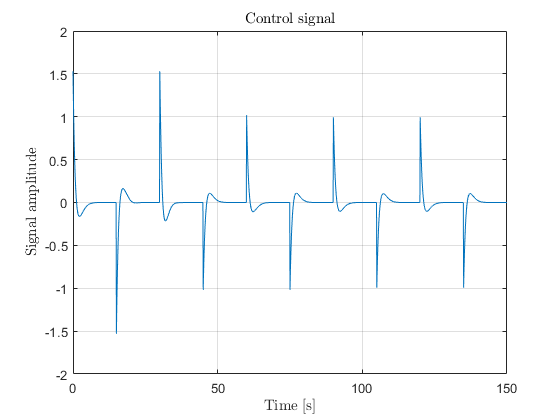


figure, 
plot(t, command); grid;
title("Control signal", "Interpreter", "Latex");
xlabel("Time [s]", "Interpreter", "latex");
ylabel("Signal amplitude", "Interpreter", "latex");

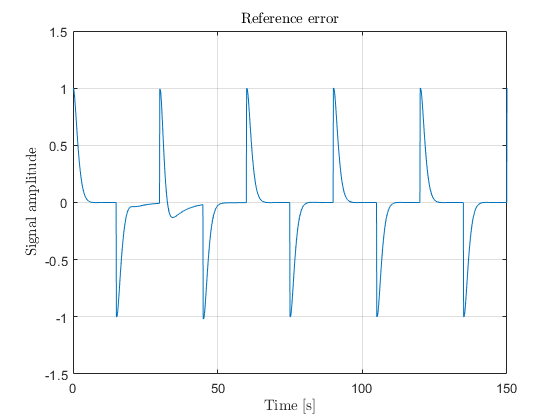


figure, 
plot(t, error); grid;
title("Reference error", "Interpreter", "Latex");
xlabel("Time [s]", "Interpreter", "latex");
ylabel("Signal amplitude", "Interpreter", "latex");

function [num, den] = getDiscreteCompensator(a1, b1, Te, Wn, zeta)
    Tf = -Te/(log(-1 - a1));
    Kf = b1/(Tf*(exp(-Te/Tf) - 1) + Te);
    ca0 = 1 + 1/(zeta*Wn*Te);
    ca1 = 1 - 1/(zeta*Wn*Te);
    cb0 = 1 + 2*Tf/Te;
    cb1 = 1 - 2*Tf/Te;
    num = (Wn/(2*Kf*zeta))*[cb0 cb1];
    den = [ca0 ca1];
    num = num/den(1);
    den = den/den(1);
end